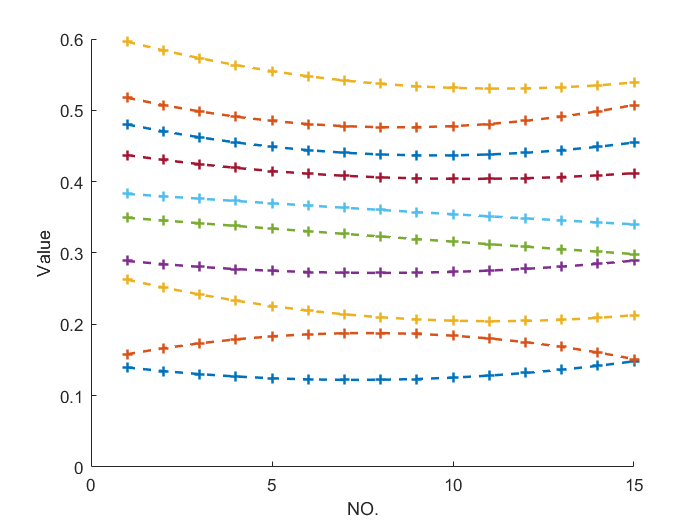

close all
clc
clear
% 读取 Excel 文件中的数据
vd = xlsread('FIG-VGTH\vd.xlsx');
vh = xlsread('FIG-VGTH\vh.xlsx');
vr = xlsread('FIG-VGTH\vr.xlsx');
vl = xlsread('FIG-VGTH\vl.xlsx');
% 将矩阵转换为一维数组
vd1 = reshape(vd, [15,12]);
vr1 = reshape(vr, [15,12]);
vh1 = reshape(vh, [1,180]);
vl1 = reshape(vl, [1,180]);
figure(1)
% 绘制曲线图
for i=3:12
beta=1:15;
p = polyfit(beta, vd1(:,i)'*1-0.16, 2);
yvr1= polyval(p, beta);
%plot(vd1(:,i)'*1-0.16-0.03,'--o','LineWidth', 1.5);
hold on;
p = polyfit(beta, vr1(:,i)', 2); % 进行二次拟合，获取多项式系数
yvr2= polyval(p, beta); % 计算拟合曲线的纵坐标
plot(yvr2,'--+','LineWidth', 1.5);
%plot(vh1(1,40:120), 'LineWidth', 1.5);
%plot(vl1(1,40:120), 'LineWidth', 1.5);
ylim([0,0.6])
% 设置图例和坐标轴标签
%legend('fomular', 'rvt', 'hvt', 'lvt');
xlabel('NO.');
ylabel('Value');
end
% 设置图像标题和字体大小
%title('Four Matrix Plots', 'FontSize', 16);
fig=gcf;
%fig.PaperPosition = 'auto';
fig_pos=fig.PaperPosition;
fig.PaperSize=[fig_pos(3),fig_pos(4)];
saveas(gcf,'vgth.pdf')


figure(2)
% 绘制曲线图
%plot(vd1(1,40:120)-0.16, 'LineWidth', 1.5);
vd1 = reshape(vd, [1,180]);
vr1 = reshape(vr, [1,180]);
vh1 = reshape(vh, [1,180]);
vl1 = reshape(vl, [1,180]);
beta=70:1:80;
p = polyfit(beta, vr1(1,70:1:80)./(vd1(1,70:1:80)-0.16)-1, 2);
yvr1= polyval(p, beta);
plot(beta,yvr1,'--o', 'LineWidth', 1.5);
hold on;
% plot(vh1(1,40:120)./(vd1(1,40:120)-0.16)-1, 'LineWidth', 1.5);
% plot(vl1(1,40:120)./(vd1(1,40:120)-0.16)-1, 'LineWidth', 1.5);

% 设置图例和坐标轴标签
legend('fomular', 'rvt', 'hvt', 'lvt');

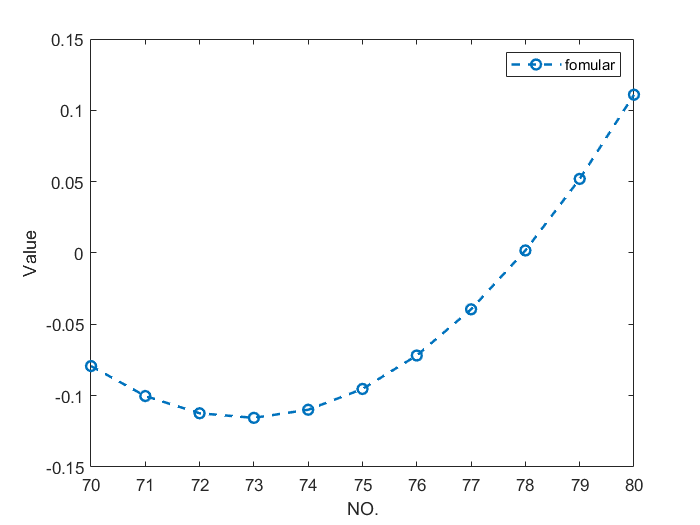

%ylim([0,1])
xlabel('NO.');
ylabel('Value');

% 设置图像标题和字体大小
%title('Four Matrix Plots', 'FontSize', 16);
fig=gcf;
%fig.PaperPosition = 'auto';
fig_pos=fig.PaperPosition;
fig.PaperSize=[fig_pos(3),fig_pos(4)];
saveas(gcf,'vgth2.pdf')